# Write Tests for Custom UI Component

This example shows how to write a test that performs a gesture on a custom UI component created using App Designer. The test uses the MATLAB® app testing framework. For more information, see [Overview of App Testing Framework](docid:matlab_prog#mw_ae92f033-bff3-4de0-8771-5462af811eae).

To test gestures on a custom UI component, use these steps:

- Create the custom UI component in App Designer.

- Give test classes access to the underlying UI components that make up the custom component.

- Write a test class that performs gestures on the underlying UI components.

## Create Custom UI Component in App Designer

This example uses the `ColorPickerComponent` custom UI component. The component consists of:

- Three numeric edit fields, stored as private properties named `RedField`, `GreenField`, and `BlueField`, to enter and display the RGB values of the selected color

- A button, stored as a private property named `Button`, that shows the current color and opens a color picker when a user clicks it

Open the `ColorPickerComponent` file in App Designer.

appdesigner("ColorPickerComponent.mlapp")

## Give Test Classes Access to Underlying UI Components

To write a test class that performs a gesture on an underlying UI component in the custom component, the test class must have access to that underlying UI component. For example, to write a test that changes the value of an edit field in the `ColorPickerComponent`, the test class must have access to the `NumericEditField` object. To give the test class access, with the component file open in App Designer, select the `ColorPickerComponent` node in the Component Browser. Then, under **Testing**, select **Give Test Cases Access**.

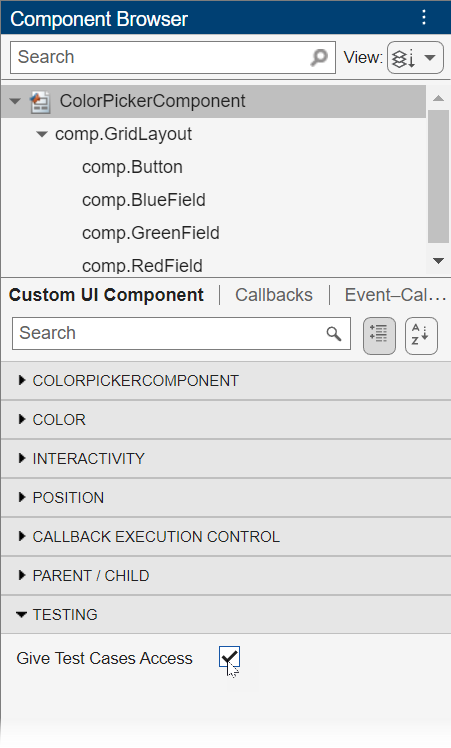

## Write Test Class

Use the app testing framework to write a test for the component. Create a test class named `ColorPickerComponentTest` with a single test method named `testEditField`. Implement these actions in the test method:

- Create a test callback function and a `ColorPickerComponent` object in a UI figure.

- Restore the environment after testing by deleting the figure when the test is complete.

- Enter a value in the `RedField` edit field of the component by using the [`type`](docid:matlab_ref#mw_72897934-d1c7-4bbf-b2ed-08d56f36145e) gesture method.

- Verify that the button color updates as expected and that the callback function was called.

Here is the complete code for the `ColorPickerComponentTest` test class.

Run the test. As the test runs, you can see the `Test` method open a figure window with the color picker component, perform a type gesture on an edit field to update the button color, and then close the figure window.

result = runtests("ColorPickerComponentTest")

*Copyright 2023 The MathWorks, Inc.*